# Stock Data - PCA Outlying Dates I

In this exercise, you will perform principal component analysis on daily stock returns, compute and visualize the variance explained by each principal component.

## 1.

Load data from `stockData_withReturns.mat`.

load stockData_withReturns.mat

## 2.

Use the `zscore`function to normalize the stock returns.

retsNorm = zscore(rets)

retsNorm =     0.9053   -0.8951    0.2532    1.0939   -0.4994   -0.1900    0.5393   -1.0114   -0.4670   -0.2864   -0.0601    0.0823   -0.0026   -0.2058   -1.1492   -0.7003    0.1223   -0.7758   -0.5571   -0.9853   -0.2413   -0.9020    0.3164   -0.1723   -0.0854   -0.1781   -0.5515   -0.1165    0.1625   -0.1247    0.6410   -0.5029   -0.0082    0.0139   -0.1525   -0.6469    0.1117   -0.3399   -0.7082   -0.2872   -0.1686    0.3412   -0.3044   -0.2184    0.1450   -0.0424   -0.5056   -0.7422   -0.1262   -0.3539
   -0.6084    0.4673    0.2579    6.0079    0.4023    0.3570   -0.0905   -0.3700    0.1973   -0.1254    0.0536   -0.3860   -0.4823    0.3796   -0.1825    0.2787    0.5339   -0.0617    0.5095    0.1104    0.0566    0.2284   -0.3593   -0.0917   -0.3667    0.2539    0.7005   -0.2945   -0.3622   -0.2626   -0.2387    0.0171    0.5898   -0.3011    0.7320   -0.4694   -0.0996    0.1169    0.0406    0.2138    0.0727   -0.2775   -0.1894    0.2016    1.7717    0.0087   -0.0038   -0.5652   -0.27

## 3.

Perform principal component analysis on the normalized stock returns and ask for at least 4 outputs.

[pcs, scrs, vexp, tstats] = pca(retsNorm)

pcs =     0.0858   -0.0737   -0.0156   -0.0583   -0.0168    0.0353   -0.1079    0.1253   -0.0859   -0.0298    0.0307    0.0530   -0.0550   -0.0217    0.0476   -0.0831   -0.0047   -0.0106   -0.0377   -0.0234    0.0319    0.0643   -0.0753   -0.0270   -0.1194    0.1403   -0.1335   -0.0249    0.0202    0.0120    0.0425    0.0304    0.1173    0.1790   -0.0196   -0.1280    0.0272   -0.2152   -0.0188   -0.0746   -0.1591    0.0105   -0.1988   -0.2549    0.2812    0.0306   -0.2345    0.1153    0.0525    0.0516
    0.0908   -0.0461   -0.0260   -0.1072   -0.0674   -0.0102   -0.0320    0.1161    0.0600    0.0567    0.1067    0.0100   -0.0317   -0.0052   -0.1213   -0.1260    0.1011   -0.0501   -0.0306    0.0707    0.0731    0.0153    0.0799   -0.0131    0.0082    0.0099    0.0808   -0.0449    0.1088   -0.1336    0.1393   -0.1005   -0.0717   -0.1468    0.0696    0.1558   -0.0072    0.1479   -0.0702   -0.0807   -0.1685   -0.0657    0.2420   -0.1374   -0.0073    0.0656   -0.1615   -0.0064   -0.0410   

scrs =    -3.2023    0.2051   -0.6274    0.8666   -0.1192    0.0649   -0.4364    1.1464   -1.0323   -0.2587    0.2803    0.1342   -0.9211    0.7515   -1.1531    0.1856   -0.4523   -1.4313    0.8116   -1.1442   -1.0536    1.0606    0.3340   -0.9153   -0.2386    0.9151    0.7617   -0.7013    0.5054   -0.6197   -0.7982   -0.6126   -0.2565    1.2221   -1.3884   -0.1629   -1.1386    0.3650    1.3730   -0.2968   -0.8123    0.5958    0.8313    1.3743    1.1283   -1.6936   -0.7042    0.5633   -0.9180   -0.6189
    0.8624   -2.8639   -0.6738   -0.9067    0.2823   -0.1962   -0.2708    0.5098    1.3348   -0.7607    0.6715   -0.4850   -2.6086    2.0100    0.6454    0.5405    0.7264    1.2796   -0.9099   -1.2351   -0.1299    2.4546    1.2651   -2.0409    0.5998    0.4215   -0.7965    1.3852    0.2854   -1.3143    0.4257    1.0818    0.9519   -0.3825    0.3040    0.4081   -1.1244    0.2173    0.5872    0.3646   -0.8157    0.2071    1.3293   -0.3855   -0.7350    0.1389    0.9750   -0.2836    0.1280  

vexp =    43.2931
    6.5117
    2.5783
    2.1537
    1.8589
    1.4901
    1.4028
    1.3227
    1.2689
    1.2182


tstats =    92.9470
   95.5335
   47.7366
   51.2327
   42.6606
   67.9056
   83.4635
   95.4781
   69.1084
   75.5190


## 4.

Create a Pareto chart of the variance explained by the principal components.

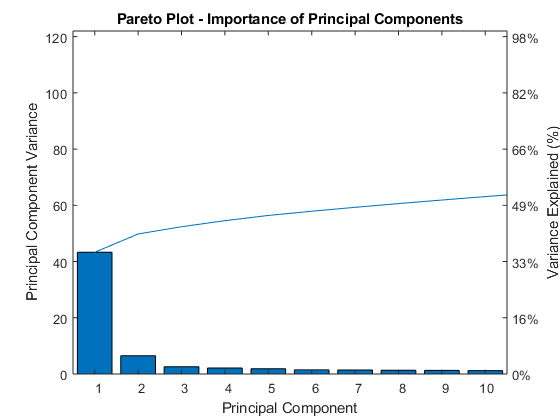

[~,ax] = pareto(vexp);
xlabel('Principal Component')
ylabel(ax(2),'Variance Explained (%)')
ylabel(ax(1),'Principal Component Variance')
title('Pareto Plot - Importance of Principal Components')

## 5.

Create a histogram of the t-squared statistics (the fourth output from `pca`).

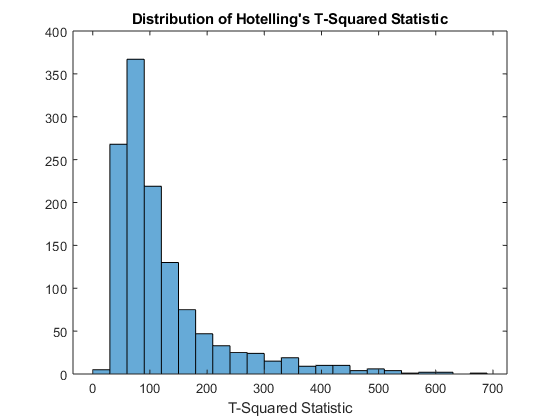

histogram(tstats)
xlabel('T-Squared Statistic')
title('Distribution of Hotelling''s T-Squared Statistic')